% Define folder and file name
%folder = 'positions_data_20250428_165242_exp1'; exp class
%folder = 'positions_data_pg_home_test1_20250502_094237'; first but steps
%are calculated wrong, now fixed
%folder = 'positions_data_pg_home_test3_20250502_115607'; %not bad results here, we see the anchors but slowly moving, the werable is left still 5 seconds at every step
%folder = 'positions_data_pg_home_test4_20250502_122138'; %quite bad here, we did a turnaroud but eveidently there was not time for dta to be sent, position is completely wrong should be a cycle. step distance id calculated quite good now at least.
%folder = 'positions_data_pg_home_test6_20250502_123323'; %distance with step counter is nearly perfet, also setting my age correctly, position in not updating real time, the movement walking is too fast to be catched. even rssi plot is not totally correct
%folder = 'positions_data_20250505_143936'; %class data, exp2. 3 times on a
%single line walking normally
%folder = 'positions_data_20250505_144653'; %class data, exp3. 3 times a  single line walking slower
%folder = 'positions_data_20250505_145109'; %class data, exp4. 3 times a  single line walking very very slow. waiting 5 secs between a step and the following
%folder = 'positions_data_20250505_150717'; %class data, exp4. 3 times a  single line walking normlly, changed code of anchors and wearable. the rssi is better but the beginnning is wrong.
%folder = 'positions_data_min_s_20250505_151707';
%folder = 'positions_data_min_s2_20250505_152326';

%folder = 'positions_data_min_turncomplete_20250505_165323';
%folder = 'positions_data_min_1line_20250505_170232'
%folder = 'positions_data_min_s_20250526_145435' min1 with professors, in
%pocket
folder = 'positions_data_min_s2_20250526_150940' %min2 with professor, in hand

folder = 'positions_data_min_s2_20250526_150940'

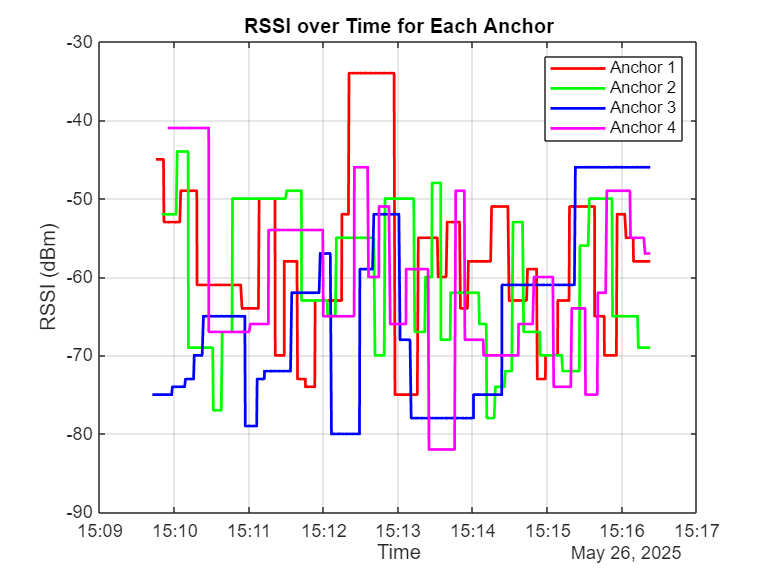



file = fullfile(folder, 'wearable_data.csv'); 

% Read the CSV file
data = readtable(file);

% Extract time and RSSI columns
time1 = data.timestamp;
rssi1 = data.rssi_anchor1;
rssi2 = data.rssi_anchor2;
rssi3 = data.rssi_anchor3;
rssi4 = data.rssi_anchor4;

% Convert timestamp to datetime if it's in string format
if iscellstr(data.timestamp) || isstring(data.timestamp)
    time = datetime(data.timestamp, 'InputFormat', 'yyyy-MM-dd HH:mm:ss'); % Adjust format if needed
else
    time = time1;
end

%% 1. Plot RSSI values over time
figure;
plot(time, data.rssi_anchor1, 'r-', 'LineWidth', 1.5); hold on;
plot(time, data.rssi_anchor2, 'g-', 'LineWidth', 1.5);
plot(time, data.rssi_anchor3, 'b-', 'LineWidth', 1.5);
plot(time, data.rssi_anchor4, 'm-', 'LineWidth', 1.5);
xlabel('Time');
ylabel('RSSI (dBm)');
title('RSSI over Time for Each Anchor');
legend('Anchor 1', 'Anchor 2', 'Anchor 3', 'Anchor 4');
grid on;

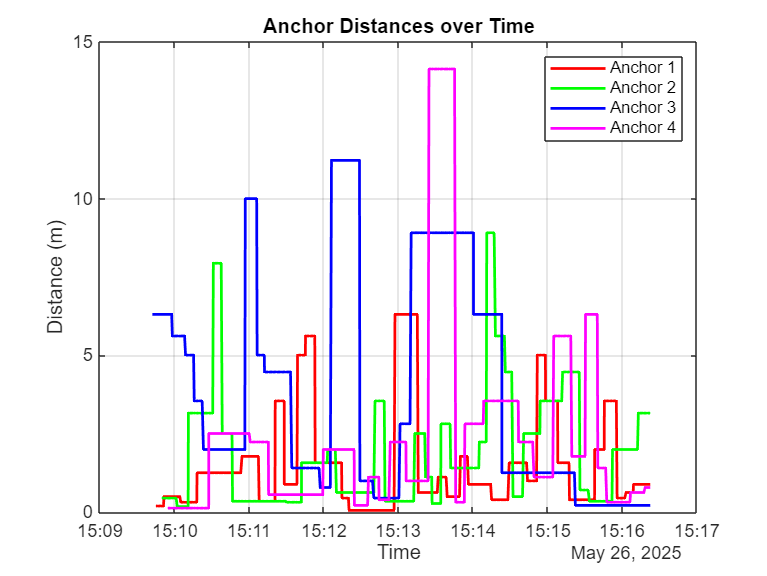


%% 2. Plot distances over time
figure;
plot(time, data.distance_anchor1, 'r-', 'LineWidth', 1.5); hold on;
plot(time, data.distance_anchor2, 'g-', 'LineWidth', 1.5);
plot(time, data.distance_anchor3, 'b-', 'LineWidth', 1.5);
plot(time, data.distance_anchor4, 'm-', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Distance (m)');
title('Anchor Distances over Time');
legend('Anchor 1', 'Anchor 2', 'Anchor 3', 'Anchor 4');
grid on;

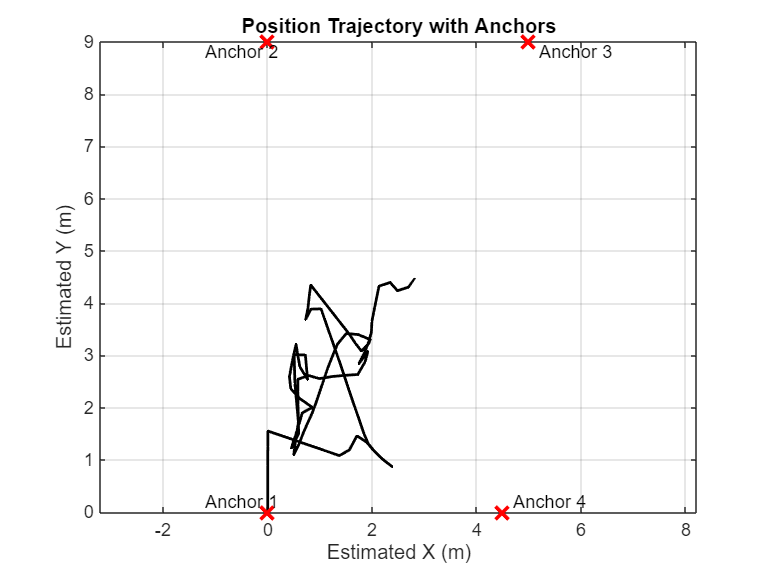


%% 3. Plot position trajectory
figure;
plot(data.estimated_x, data.estimated_y, 'k-', 'LineWidth', 1.5); hold on;

% Add anchors positions
anchor_positions = [0, 0; 0, 9; 5, 9; 4.5, 0]; %EP2
%anchor_positions = [0, 0; 6.5, 0; 6, 4.3; 0.7, 6]; %home, livingroom

plot(anchor_positions(:,1), anchor_positions(:,2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);

% Annotate anchor names
text(anchor_positions(1,1)-1.2, anchor_positions(1,2)+0.2, 'Anchor 1', 'FontSize', 10);
text(anchor_positions(2,1)-1.2, anchor_positions(2,2)-0.2, 'Anchor 2', 'FontSize', 10);
text(anchor_positions(3,1)+0.2, anchor_positions(3,2)-0.2, 'Anchor 3', 'FontSize', 10);
text(anchor_positions(4,1)+0.2, anchor_positions(4,2)+0.2, 'Anchor 4', 'FontSize', 10);

xlabel('Estimated X (m)');
ylabel('Estimated Y (m)');
title('Position Trajectory with Anchors');
grid on;
axis equal;

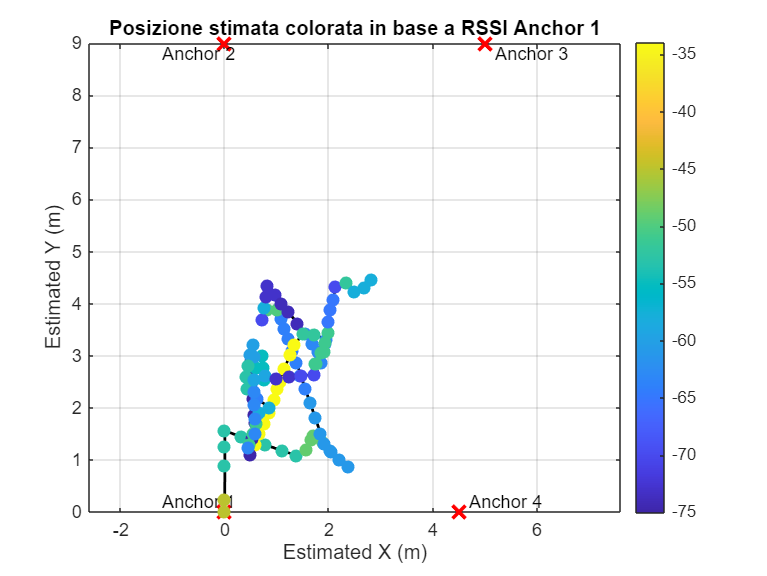

%% 4. Scatter plot stimato X-Y colorato da RSSI

scatter(data.estimated_x, data.estimated_y, 50, data.rssi_anchor1, 'filled');
colorbar;
xlabel('Estimated X (m)');
ylabel('Estimated Y (m)');
title('Posizione stimata colorata in base a RSSI Anchor 1');
grid on;
axis equal;


%% 5. Plot all distance metrics over time
figure;
subplot(2,1,1)
plot(time, data.step_distance_m, 'r-', 'LineWidth', 1.5); hold on;
plot(time, data.position_distance_m, 'g-', 'LineWidth', 1.5);
plot(time, data.fused_distance_m, 'b-', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Distance (m)');
title('Distance Metrics over Time');
legend('Step Distance', 'Position Distance', 'Fused Distance',Location='southoutside', Orientation='horizontal');
grid minor;


subplot(2,1,2)
plot(time, data.total_step_distance_m, 'c-', 'LineWidth', 1.5); hold on;
%plot(time, data.total_position_distance_m, 'm-', 'LineWidth', 1.5);
%plot(time, data.total_fused_distance_m, 'k-', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Distance (m)');
legend('Total Step Distance', 'Total Position Distance', 'Total Fused Distance' ,Location='southoutside', Orientation='horizontal');

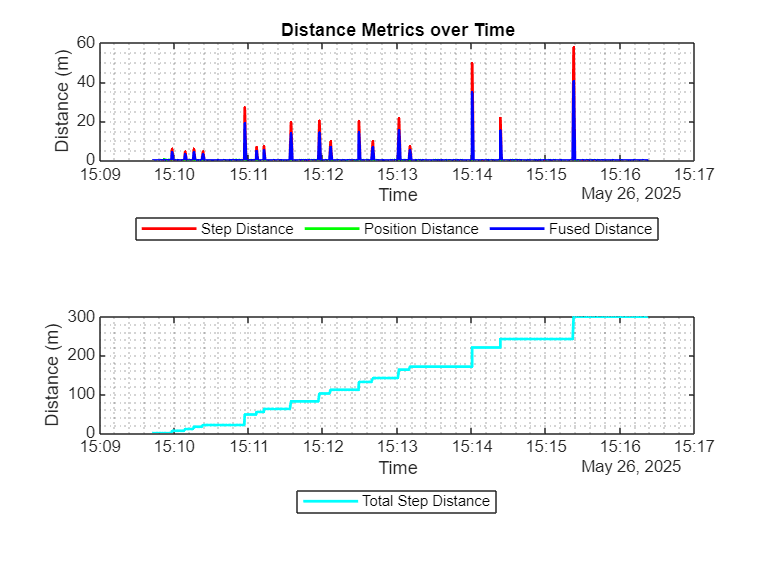

grid minor;

n_tour_around_done = 14;
distance_that_should_be_done = computePerimeter(anchor_positions) * n_tour_around_done;
fprintf('we should have travelled: %.2f m\n', distance_that_should_be_done);

we should have travelled: 385.19 m



function perimeter = computePerimeter(points)
% computePerimeter Calcola il perimetro di un poligono dati i suoi vertici
%
% Input:
%   points - matrice Nx2 con le coordinate (x,y) dei vertici
%
% Output:
%   perimeter - perimetro totale (in metri)

    % Chiudiamo il poligono aggiungendo il primo punto alla fine
    points_closed = [points; points(1,:)];
    
    % Differenze tra punti consecutivi
    deltas = diff(points_closed, 1, 1);
    
    % Distanze euclidee tra punti consecutivi
    distances = sqrt(sum(deltas.^2, 2));
    
    % Somma delle distanze
    perimeter = sum(distances);
end
